# Práctica 2 - Cortocircuitos II - Apartado E

#### Falta monofásica (F10) en el punto F3

## Sistemas Eléctricos y de Potencia

### Subgrupo 10

NOTA. Aquí se usa el índice 3 para lasecuencia homopolar debido a la negativa de Matlab a trabajar con vectores empezando en 0.

format shortG
sympref('FloatingPointOutput', true);
if ~exist('ZF1N', 'var')
    evalc('Practica2B');
end

## Circuito equivalente en secuencia directa

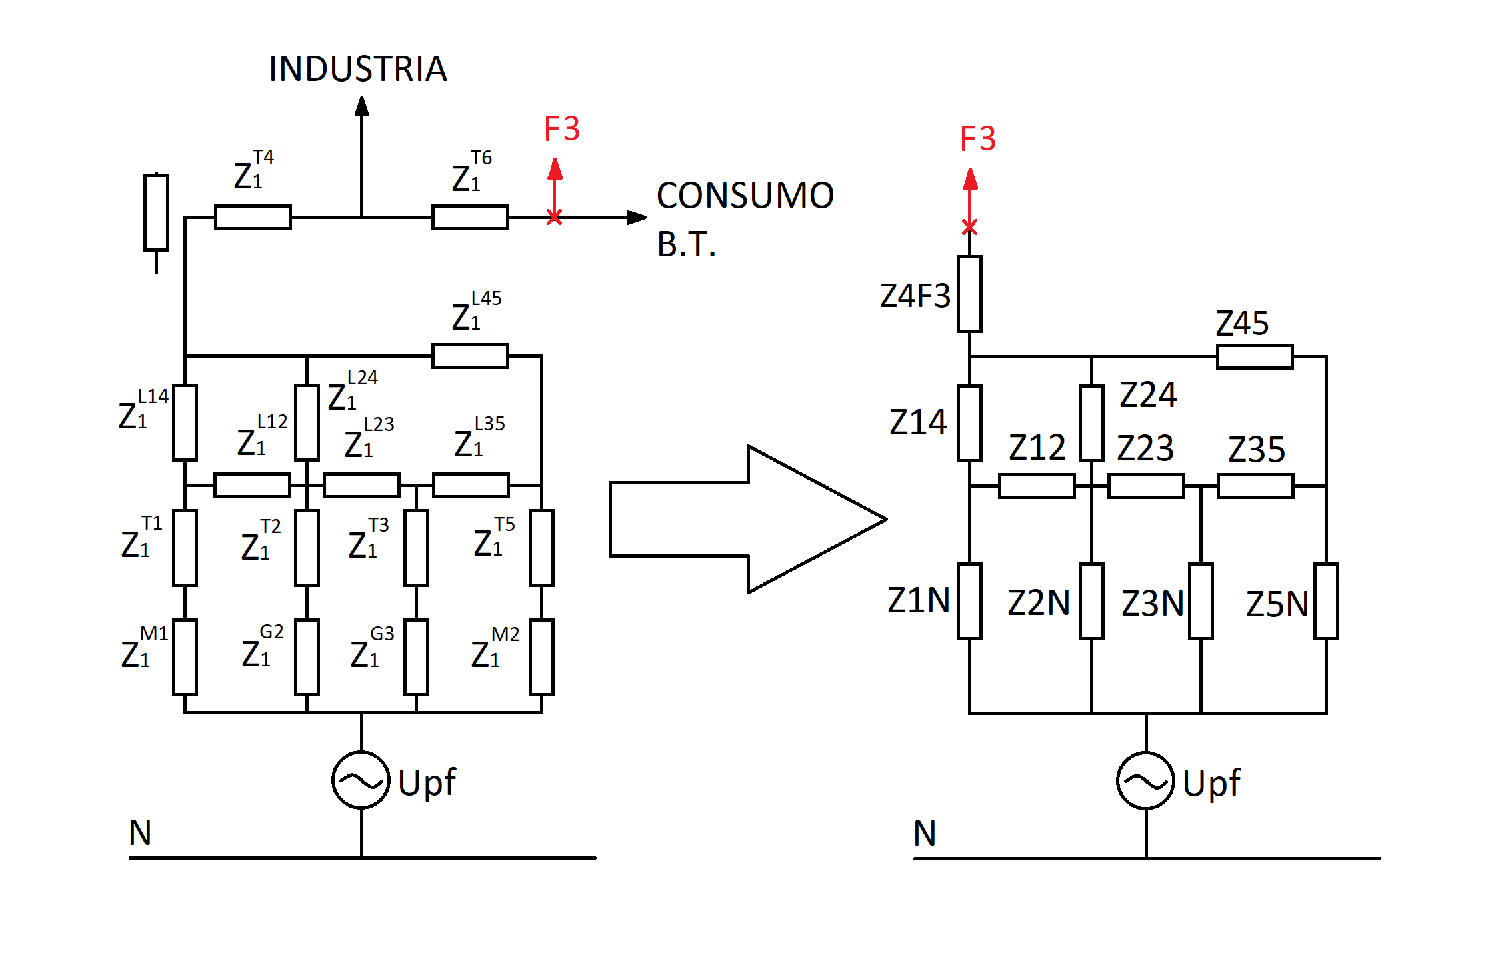

% Datos
Ubase_F3 = Ubase7;
Ibase_F3= Sbase/(sqrt(3)*Ubase_F3);
Upf_F3 = 1.05;

imshow("F3.png");


% Valores de todas las admitancias iniciales
Y1N = 1/(ZT1pu(1) + ZM1pu(1));
Y12 = 1/ZL12pu(1);
Y14 = 1/ZL14pu(1);
Y2N = 1/(ZT2pu(1) + ZG2pu(1));
Y23 = 1/ZL23pu(1);
Y24 = 1/ZL24pu(1);
Y3N = 1/(ZT3pu(1) + ZG3pu(1));
Y35 = 1/ZL35pu(1);
Y45 = 1/ZL45pu(1);
Y4F3 = 1/(ZT4pu(1) + ZT6pu(1));
Y5N = 1/(ZT5pu(1) + ZM2pu(1));

## Impedancia equivalente en secuencia directa e inversa

La impedancia en secuencia directa es la misma que en secuencia directa (Z1 = Z2). 

Se calcula mediante la matriz de barras, considerando que el índice 6 corresponde al punto de falta F3 (no al nodo 6).

Nótese que la impedancia total es aproximadamente igual a solamente la del trafo T6 (que es 5.7037j pu), haciendo que el resto del cicruito sea casi despreciable.

% Matriz de admitancias
Ybarras1 = [Y1N+Y12+Y14, -Y12           , 0           , -Y14            , 0          , 0    ;
            -Y12       , Y2N+Y12+Y23+Y24, -Y23        , -Y24            , 0          , 0    ;
            0          , -Y23           , Y3N+Y23+Y35 , 0               , -Y35       , 0    ;
            -Y14       , -Y24           , 0           , Y14+Y24+Y45+Y4F3, -Y45       , -Y4F3;
            0          , 0              , -Y35        , -Y45            , Y5N+Y35+Y45, 0    ;
            0          , 0              , 0           , -Y4F3           , 0          , Y4F3 ]

Ybarras1 =             0 -     31.785i            0 +     24.891i            0 +          0i            0 +     6.2229i            0 +          0i            0 +          0i
            0 +     24.891i            0 -     45.948i            0 +     12.446i            0 +      4.356i            0 +          0i            0 +          0i
            0 +          0i            0 +     12.446i            0 -     21.642i            0 +          0i            0 +      4.356i            0 +          0i
            0 +     6.2229i            0 +      4.356i            0 +          0i            0 -     15.104i            0 +      4.356i            0 +    0.16938i
            0 +          0i            0 +          0i            0 +      4.356i            0 +      4.356i            0 -     9.1547i            0 +          0i
            0 +          0i            0 +          0i            0 +          0i            0 +    0.16938i            0 +          0i            0 -    0.16938i



% Matriz de impedancias
Zbarras1 = inv(Ybarras1)

Zbarras1 =             0 +    0.14037i            0 +    0.10951i            0 +    0.08217i            0 +    0.11824i            0 +   0.095359i            0 +    0.11824i
            0 +    0.10951i            0 +    0.11361i            0 +   0.083366i            0 +    0.10489i            0 +   0.089577i            0 +    0.10489i
            0 +    0.08217i            0 +   0.083366i            0 +    0.11326i            0 +   0.086239i            0 +   0.094924i            0 +   0.086239i
            0 +    0.11824i            0 +    0.10489i            0 +   0.086239i            0 +    0.18437i            0 +    0.12876i            0 +    0.18437i
            0 +   0.095359i            0 +   0.089577i            0 +   0.094924i            0 +    0.12876i            0 +    0.21567i            0 +    0.12876i
            0 +    0.11824i            0 +    0.10489i            0 +   0.086239i            0 +    0.18437i            0 +    0.12876i            0 +     6.0881i



% Impedancia equivalente en sec. 1 (pu)
Z1F3_eq = Zbarras1(6,6)

Z1F3_eq =             0 +     6.0881i



% Impedancia equivalente en sec. 2 (pu)
Z2F3_eq = Z1F3_eq

Z2F3_eq =             0 +     6.0881i


## Impedancia en secuencia homopolar

Solo es la del trafo T6, al estar en el secundario del trafo Dyn

% Impedancia equivalente en sec. 0 (pu)
Z0F3_eq = ZT6pu(3)

Z0F3_eq =             0 +     5.7037i


## Valor de la corriente de falta monofásica (F10) en el punto F1

Los valores de las corrientes de cada secuencia son iguales, J1 = J2 = J0 = 1/3 JF = Upf/(Z0 + Z1 + Z2)

% Valor por unidad en función de x
JF3_pu = 3*Upf_F3/(Z1F3_eq + Z2F3_eq + Z0F3_eq)

JF3_pu =             0 -    0.17617i



% Valor real (en amperios) 
JF3 = JF3_pu*Ibase_F3

JF3 =             0 -      24793i


## Corrientes de secuencia y de fase

% Corrientes de secuencia (en amperios)
J012_F3 = 1/3*[JF3; JF3; JF3]

J012_F3 =             0 -     8264.3i
            0 -     8264.3i
            0 -     8264.3i



% Corrientes de fase (en amperios)
Jabc_F3 = T*J012_F3

Jabc_F3 =             0 -      24793i
   2.7285e-12 + 9.0949e-13i
   2.7285e-12 + 9.0949e-13i
